# Nonlinear Reinforcement Function Example 1

## Plotting $V=\left(0,1\right),X_0 =\left(1,0\right)$

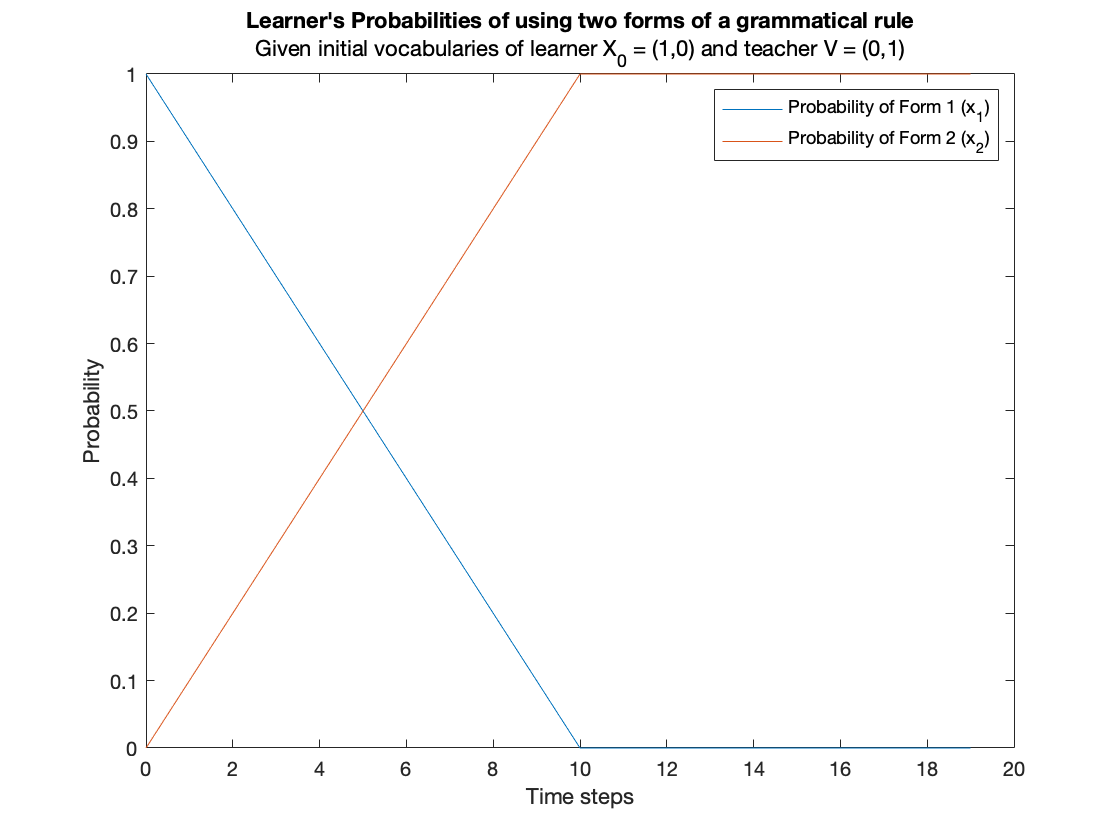

clear all;
hold off;

x_10 = 1;
x_20 = 0;
V = [0 1]; % Initial distribution of teacher
s = 0.1; % Learning rate
n = 2; % number of variants
T = 20; % Number of time steps to take

% Define our initial vectors with x1 and x2 values as empty 
X1 = NaN(T, 1)

X1 =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


X2 = NaN(T, 1)

X2 =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


X1(1) = x_10;
X2(1) = x_20;
% First plot the growth of form x_0
for t = 2:T
    X1(t) = X1(t-1) - F(X1(t-1),n,s);
    X2(t) = X2(t-1) + F(X1(t-1),n,s);
end
TVector = 0:1:(T-1)

TVector =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19


plot(TVector, X1);
hold on;
plot(TVector, X2);
hold on;
legend("Probability of Form 1 (x_1)","Probability of Form 2 (x_2)" )
title("Learner's Probabilities of using two forms of a grammatical rule")
subtitle("Given initial vocabularies of learner X_0 = (1,0) and teacher V = (0,1)")
xlabel("Time steps")
ylabel("Probability")

function [out] = F(x, n, s)
    comparator = s / (n-1);
    if x > comparator
        out = comparator;
    else
        out = x;
    end
end